# Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.1.6. Análisis localizado en el dominio del tiempo (v3.0)

### Objetivo

El objetivo de este ejercicio es aplicar los conceptos implicados en el análisis localizado aplicado al procesamiento temporal de señales y la evaluación de los criterios generales usados en el cálculo de espectrogramas. Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Señales disponibles

#### Señales de audio

Capturadas con un micrófono, con una frecuencia de muestreo de 16KHz:

- insn-sepc-ingenierianeurosensorial.wav, pronunciada por una hablante femenina

- insn-jmg-ingenierianeurosensorial.wav, pronunciada por un hablante masculino

### Funciones disponibles

Para facilitar el análisis basado en espectrograma, se proporciona una función mysfft, de la que copiamos a continuación la información sobre su prototipo:

% function: [STFT, f, t] = mystft(x, win, hop, nfft, fs, ,,,)
%
% Input:
% x           Signal in the time domain
% win         Analysis window function (its length will define the
%             signal window length to use)
% hop         Hop size (frame shift value), in samples
% nfft        Number of FFT points
% fs          Sampling frequency, Hz
%
% Optional (can be provided in any order):
% 'doNorm'    Normalize to get amplitudes consistent with
%             half amplitude in real signals, also take
%             into account no normalization for DC and
%             fnyquist components
% 'doModule'  Returns module (abs) of fft values
% 'doLog'     Returns dB value of module (abs) of fft values, will
%             set 'doModule' automatically
% 'doPlot'    Plots spectrogram. Requires either doModule or doLog
% 'doFlim'    Use next argument to set frequency axis plotting limits
%             that must be [fmin fmax], in Hz. Only for plotting, will
%             set doPlot automagically
% 'doTlim'    Use next argument to set time axis plotting limits
%             that must be [tmin tmax], in seconds. Only for plotting, will
%             set doPlot automagically
%
% Output:
% STFT        STFT-matrix (only unique points, time
%             across columns, frequency across rows), it will be
%             normalized, converted to module or dBs depending on the
%             optional flags used. If none is provided, it will given
%             as standard FFT complex values.
% f           Frequency vector indexes, in Hz
% t           Time vector indexes, in s (will be the time instants
%             corresponding to the middle of each analysis window)


## Desarrollo

- Borre variables, figuras y ventana de comandos:

clear all;
close all force;
clc;

Se pide ahora implementar un esquema general de análisis localizado, a partir de la definición de los parámetros fundamentales,que abordaremos en varios pasos:

- Lo primero es descargar los datos correspondientes. Utilice cualquiera de las señales de audio que le indicamos más arriba (puede oirlas si dispone de unos auriculares, con el comando sound(x, fs))

% Here you will have to download/generate the appropriate data, and store
% it in vector x. If fs is provided in the data or can be calculated from
% it, there is no need to set its value in the next section
audioFileName='audio/insn-jmg-ingenierianeurosensorial.wav';
[x, fs] = audioread(audioFileName);
signalLengthSamples  = length(x);
signalLengthSeconds  = signalLengthSamples/fs;
timeIndexes = 0: 1/fs: signalLengthSeconds - 1/fs;

- Lo segundo es la definición de los parámetros del análisis que vimos en clase. Se proporcionan unos valores iniciales  Defina :

% Setting general parameters
fs                 = 16000;                  % Set to adequate value if not provided in the preceeding block
frameSizeSeconds   = 0.0250;                 % Set to adequate value
frameShiftSeconds  = frameSizeSeconds / 2;   % Set to adequate value, 50% of analysis windows by default

frameSizeSamples   = frameSizeSeconds * fs;  % Convert properly
frameShiftSamples  = frameShiftSeconds * fs; % Convert properly

fftSize            = max(4096, 2^nextpow2(frameSizeSamples)); % Set to adequate value

analysisWindow     = hamming(frameSizeSamples); % Set to adequate windowing signal
%analysisWindow     = boxcar(frameSizeSamples); % Set to adequate windowing
%signal. If we use boxcar, it's possible to see the effect of the magnitude
%spreading at around 0.79-0.83 seconds, in two vertical bands in high
%frequency for the insn-jmg-ingenieraneurosensorial.wav file

% Comentarios y discusion:
% + Discuta y justifique si los valores proporcionados son razonables
%   teniendo en cuenta el tipo de señal y an analisis que vamos a realizar
%   a continuacion.

%fs: Gran parte de la información util del habla se encuentra por debajo de 8 kHz. Por tanto, una frecuencia de muestreo de 16 kHz satisface el
%criterio de Nyquist.

%duracion de la ventana: Nventana=0.025*16000 = 400 muestras. Utilizar un tamaño pequeño de ventana permite estudiar pequeños fragmentos de señal,
%aproximando su comportamiento a una señal estacionaria en cada intervalo.

%desplazamiento de ventana: se establece que el desplazamiento entre ventanas es del 50%. Esto indica que para 2 ventanas de 400 muestras, van
%a compartir 200 muestras con el mismo valor de señal. Esto permite una evolucion temporal continua y reduce la posibilidad de perder información
%de señal entre transiciones de ventanas.

%tamaño de ventana: se utiliza una FFT de 4096 puntos, superior al tamaño de la ventana (400 muestras). Esto permite obtener una representación espectral más
%densa mediante zero-padding, facilitando la visualización de los picos espectrales y la estimación de su frecuencia. Sin embargo, no aumenta la
%resolución frecuencial real, que depende fundamentalmente de la duración de la ventana de análisis.

%tipo de ventana: se utiliza una ventana Hamming, la cual permite atenuar progresivamente los extremos, reduciendo discontinuidades provocadas por
%el recorte de la señal en varios fragmentos.



- Lo tercero es la implementación del esquema de análsisis localizado en sí,que incluye el bucle de proceso, en el que se irán seleccionando ventanas de señal según los parámetros definidos. En este ejemplo inicial se pide que, para cada ventana, se calcule la energía de la misma (suma de todos los valores de muestras al cuadrado):

% Calculate the number of analysis frames for the full input signal
numAnalysisFrames   = 1 + fix((signalLengthSamples-frameSizeSamples)/frameShiftSamples);
timeFrameIndexes = (frameSizeSamples/2:frameShiftSamples:frameSizeSamples/2+(numAnalysisFrames-1)*frameShiftSamples)/fs;

% Set signalEnergy to zero
signalEnergy = zeros(1, numAnalysisFrames);

for numFrame = 0:numAnalysisFrames-1
  % Select signal window
  sampleOffset = numFrame * frameShiftSamples;
  xw = x(sampleOffset + 1 : sampleOffset + frameSizeSamples) .* analysisWindow;
  
  % Now we have thls -e signal frame selected and properly windowed
  % so that we can calculate energy, updating the signalEnergy vector
  signalEnergy(numFrame+1) = sum(abs(xw).^2);
end

- Dibuje finalmente la señal y la energía, en el mismo plot o en subplots, lo que considere mejor.

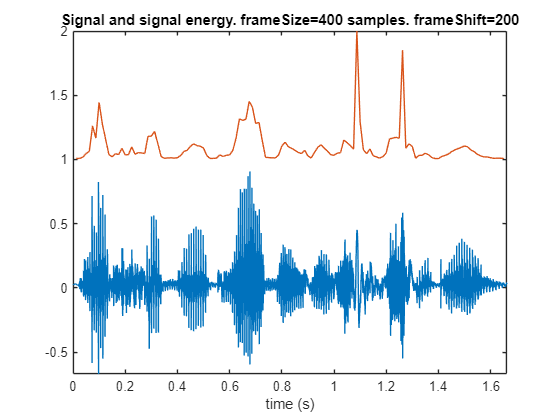


% Now plot signal and energy, in the same plot window
plot(timeIndexes, x);
hold on
plot(timeFrameIndexes, 1+ signalEnergy/max(signalEnergy));
title(['Signal and signal energy. frameSize=', num2str(frameSizeSamples), ' samples. frameShift=', num2str(frameShiftSamples)])
xlabel('time (s)');
axis tight
hold off

- Modifique el valor de frameSizeSeconds hacia valores mayores y menores (por ejemplo seleccione algunos valores entre 1ms y 1 segundo) y haga un comentario y justificación sobre lo que observe. Argumente igualmente sobre qué compromiso habría que tener en cuenta en cuando a dicha longitud, teniendo en cuenta que aquí no hemos hecho ningún cálculo espectral.

% Comentarios y discusion: 
% + Describa y justifique lo que observe 
% + Discuta si habria que adoptar algun compromiso para determinar la longitud
%   de la ventana y su impacto en el analisis temporal.

%Con ventanas pequenas (1-2.5 ms), la energia presenta mayores fluctuaciones y permite localizar con precision los cambios
%rapidos de intensidad de la senal (cambios entre tramos de sonido y silecios).

%Con ventanas grandes (100 ms-1 s), la energia varia de forma mas suave, perdiendo precision temporal. Esto provoca que sea mas
%dificil detectar cambios rapidos y pausas breves.

%Por tanto, debe alcanzarse un compromiso entre la precision temporal y la estabilidad de la medida de energía. Para analizar voz,
%una ventana de unos 25 ms permite representar adecuadamente la actividad vocal sin perder demasiado detalle temporal.



- Dibuje ahora en dos subplots la señal en el tiempo y, debajo, el espectrograma de la señal, usando como duración de la ventana 25ms y 250ms. Ajuste bien el eje temporal para que las señales se vean correctamente alineadas. Escriba en un comentario el resultado de la observación y discuta sobre cuál sería el tamaño adecuado:

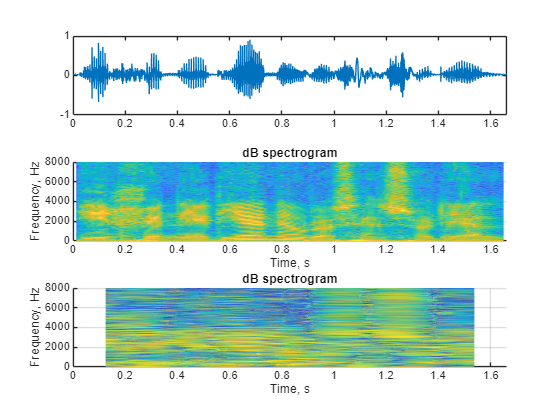

subplot(3,1,1)
plot(timeIndexes, x);
xlim([timeIndexes(1) timeIndexes(end)])
subplot(3,1,2)
mystft(x, analysisWindow, frameShiftSamples, fftSize, fs, 'doPlot', 'doModule', 'doLog', 'doNorm'); %, 'doFlim', [0 500]);
xlim([timeIndexes(1) timeIndexes(end)])


subplot(3,1,3)
analysisWindow     =hamming(frameSizeSamples*10);
mystft(x, analysisWindow, frameShiftSamples, fftSize, fs, 'doPlot', 'doModule', 'doLog', 'doNorm'); %, 'doFlim', [0 500]);
xlim([timeIndexes(1) timeIndexes(end)])



% Comentarios y discusion:
% + Describa lo que observe y justifiquelo teniendo en cuenta, como
%   siempre, la teoria vista en clase.
% + Discuta y justifique cual sera la longitud mas adecuada, pensando
%   en la aplicacion para la que vayamos a utilizar el espectrograma.

%Con una ventana de 25 ms, el espectrograma permite observar con mayor precisión temporal la evolución de la señal. Se pueden
%localizar mejor las transiciones entre sonidos, los comienzos y finales de los fragmentos sonoros y los silencios.
%La limitación es que una ventana más corta proporciona una menor resolución frecuencial, por lo que resulta más difícil distinguir
%componentes de frecuencia muy próximas.

%Con una ventana de 250 ms, aumenta la capacidad para distinguir componentes frecuenciales próximas, puesto que se analiza un intervalo
%temporal diez veces mayor. Sin embargo, los cambios que se producen dentro de la ventana quedan menos localizados temporalmente, ya que
%el espectro integra información de un intervalo más largo.

%La elección final depende de la aplicación: debe priorizarse la resolución temporal cuando interesa localizar cambios rápidos, y la
%resolución frecuencial cuando interesa distinguir componentes frecuenciales próximas.
